clear all
close all 
mask_struct = open("image_data_mask.mat");
image_struct = open("image_data.mat");


mask_img = mask_struct.out.image_data_masked;
whole_img =  mask_struct.out.image_data;

figure(1);
for i = 1:101
    imshow(whole_img(:,:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end
figure(2)
for i = 1:101
    imshow(mask_img(:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
BW = mask_img(:,:,30);
boundaries = bwboundaries(BW);

% Visualize the original image with contours
imshow(BW);
hold on;

% Loop through each boundary and plot it
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % plot y, x coordinates
end
hold off;

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
figure(2)
for i = 5:101
    BW = mask_img(:,:,i);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for i = 1:size(boundary, 1)
            black_image(boundary(i,1), boundary(i,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Display the black image with white boundaries
    imshow(black_image);
    pause(0.2)
end


figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2

    % Check for intersections and plot red points at intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the boundary (white pixel in the original image)
        if BW(cy, cx) == 255  % 255 indicates the boundary point (white)
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point (intersection)
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end



figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue circle
    
    % Find intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end


figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections and mark them as red
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end


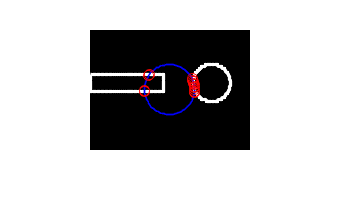

figure(4)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections using distance-based checking and mark them as red
    intersection_threshold = 1;  % Threshold for distance to detect intersections (in pixels)
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is within the threshold distance of any contour point
        distances = sqrt((contour_points(:,1) - cy).^2 + (contour_points(:,2) - cx).^2);
        if any(distances <= intersection_threshold)  % Check if any distance is below threshold
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

gay gay gay shit gówno 

% Binary mask for the current frame
BW = mask_img(:,:,30);  % Use the desired slice index

% Extract boundaries (no holes to avoid redundant processing)
boundaries = bwboundaries(BW, 'noholes');
fprintf('Number of boundaries: %d\n', length(boundaries));

Number of boundaries: 1



% Combine all contour points into a single array
contour_points = vertcat(boundaries{:});
fprintf('Number of contour points: %d\n', size(contour_points, 1));

Number of contour points: 380



% Downsample the contour points
downsample_rate = 10;  % Adjust for waypoint density
if downsample_rate <= size(contour_points, 1)
    waypoints_2d = contour_points(1:downsample_rate:end, :);
else
    waypoints_2d = contour_points;  % No downsampling if not enough points
end
fprintf('Number of waypoints: %d\n', size(waypoints_2d, 1));

Number of waypoints: 38


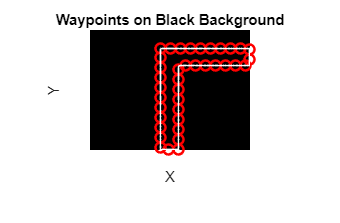


% Create a black image of the same size as BW
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Waypoints on Black Background');
xlabel('X'); ylabel('Y');
hold on;

% Plot the waypoints on the black image
plot(waypoints_2d(:,2), waypoints_2d(:,1), 'ro', 'MarkerSize', 6, 'LineWidth', 1.5);

% Optionally, plot the contours in white
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 1);  % White contours
end

hold off;

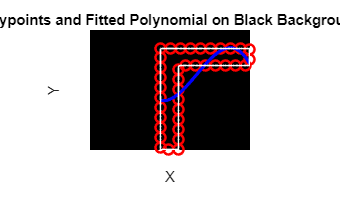

% Binary mask for the current frame
BW = mask_img(:,:,30);  % Use the desired slice index

% Extract boundaries (no holes to avoid redundant processing)
boundaries = bwboundaries(BW, 'noholes');

% Combine all contour points into a single array
contour_points = vertcat(boundaries{:});

% Downsample the contour points
downsample_rate = 10;  % Adjust for waypoint density
if downsample_rate <= size(contour_points, 1)
    waypoints_2d = contour_points(1:downsample_rate:end, :);
else
    waypoints_2d = contour_points;  % No downsampling if not enough points
end

% Separate x and y coordinates of waypoints
x = waypoints_2d(:,2);  % Column index is x-coordinate
y = waypoints_2d(:,1);  % Row index is y-coordinate

% Fit a 3rd-degree polynomial to the waypoints
p = polyfit(x, y, 3);

% Generate x-values for plotting the fitted curve
x_fit = linspace(min(x), max(x), 200);  % More points for a smooth curve

% Evaluate the polynomial to get the corresponding y-values
y_fit = polyval(p, x_fit);

% Create a black image of the same size as BW
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Waypoints and Fitted Polynomial on Black Background');
xlabel('X'); ylabel('Y');
hold on;

% Plot the waypoints in red
plot(x, y, 'ro', 'MarkerSize', 6, 'LineWidth', 1.5);

% Plot the fitted polynomial in blue
plot(x_fit, y_fit, 'b-', 'LineWidth', 2);

% Optionally, plot the contours in white
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 1);  % White contours
end

hold off;

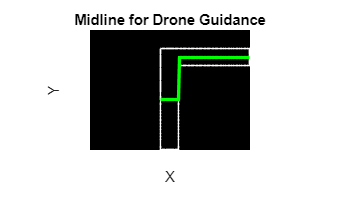

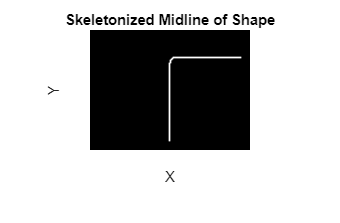

% Binary mask for the current frame (BW should be a binary image)
BW = mask_img(:,:,30);  % Use the desired slice index

% Apply morphological thinning to get the skeleton of the shape
skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed

% Create a black image to visualize the result
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Skeletonized Midline of Shape');
xlabel('X'); ylabel('Y');
hold on;

% Plot the skeleton (midline) in white
[rows, cols] = find(skeleton);
plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points

hold off;

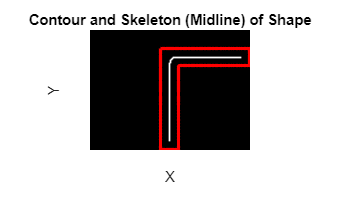

% Binary mask for the current frame (BW should be a binary image)
BW = mask_img(:,:,30);  % Use the desired slice index

% Apply morphological thinning to get the skeleton of the shape
skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed

% Find the contours of the shape using bwboundaries
boundaries = bwboundaries(BW);

% Create a black image to visualize the result
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Contour and Skeleton (Midline) of Shape');
xlabel('X'); ylabel('Y');
hold on;

% Plot the skeleton (midline) in white
[rows, cols] = find(skeleton);
plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points

% Loop through each boundary and plot it in white (contours)
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
end

hold off;

HAHAHAHAHHAAHAHHAHAHA JEST KURWA 

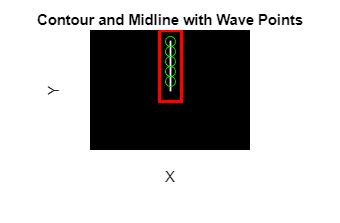

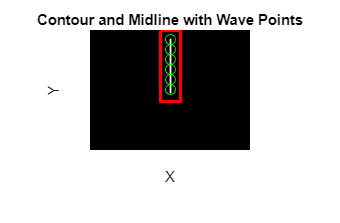

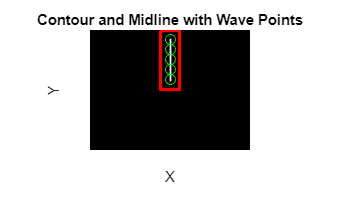

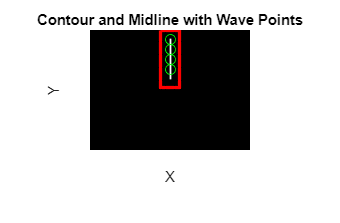

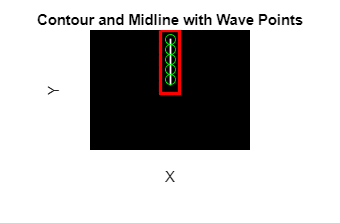

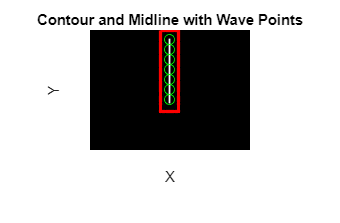

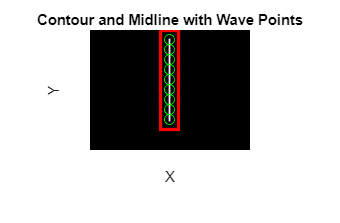

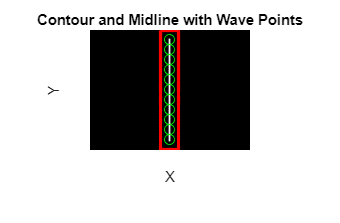

figure(4)
for sliceIdx = 5:101
    % Binary mask for the current frame (BW should be a binary image)
    BW = mask_img(:,:,sliceIdx);  % Use the desired slice index
    
    % Apply morphological thinning to get the skeleton of the shape
    skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed
    
    % Find the contours of the shape using bwboundaries
    boundaries = bwboundaries(BW);
    
    % Create a black image to visualize the result
    black_image = zeros(size(BW), 'like', BW);
    
    % Display the black image
    figure;
    imshow(black_image);
    title('Contour and Midline with Wave Points');
    xlabel('X'); ylabel('Y');
    hold on;
    
    % Plot the skeleton (midline) in white
    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points
    
    % Select wave points by downsampling the skeleton (e.g., every 5th point)
    wave_points_interval = 10;  % Downsample interval (adjust as needed)
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    
    % Plot the wave points in green to reduce the number of elements
    plot(wave_points_cols, wave_points_rows, 'go', 'MarkerSize', 6);  % Green points
    
    % Loop through each boundary and plot it in red (contours)
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
    end
    
    hold off;
    pause(0.2)
end

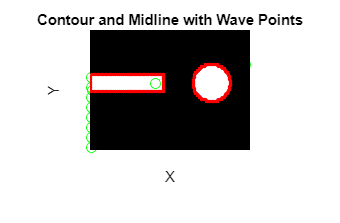

figure(4);  % Create figure once


% Loop over slices
for sliceIdx = 5:101
    % Binary mask for the current frame (BW should be a binary image)
    BW = mask_img(:,:,sliceIdx);  % Use the desired slice index
    
    % Apply morphological thinning to get the skeleton of the shape
    skeleton = bwskel(BW, 'MinBranchLength', 5);  % Adjust 'MinBranchLength' as needed
    
    % Find the contours of the shape using bwboundaries
    boundaries = bwboundaries(BW);
    
    % Create a black image to visualize the result, same size as BW
    black_image = BW;  % Use BW directly for overlaying

    % Plot the mask (BW) first (this ensures the background is always visible)
    imshow(black_image);  % Display the original mask
    hold on;  % Keep adding plots on top
    
    % Plot the skeleton (midline) in white
    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points
    
    % Select wave points by downsampling the skeleton (every 10th point)
    wave_points_interval = 10;  % Downsample interval
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    
    % Plot the wave points in green to reduce the number of elements
    plot(wave_points_cols, wave_points_rows, 'go', 'MarkerSize', 6);  % Green points
    
    % Loop through each boundary and plot it in red (contours)
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
    end
    
    % Pause a short time for animation
    pause(0.2);
end

% Set axis labels and title after the loop ends
title('Contour and Midline with Wave Points');
xlabel('X'); ylabel('Y');